初始化

%m
R = 80*1e-3;
r = 80*1e-3;
L1 = 160*1e-3;
L2 = 192*1e-3; 
toolHight = 132*1e-3;
z_p_min = 193.46*1e-3;

RRS_2RRU = RRS_2RRU_Basic(R, r, L1, L2, toolHight, z_p_min);

%simulink multibody


%simulink 导入模型关节角定义偏差
offsetThetaSim = @(theta) [pi-theta(1), theta(2), -theta(3)-pi/2];

1.测试逆运动学模块

P_pose = [193.46*1e-3, 0, 0]; %[z_p, alpha, beta]
[Tf_BTC, Tf_P] = RRS_2RRU.setEndEffectorSE3(P_pose(1), P_pose(2), P_pose(3));
thetas = RRS_2RRU.invKineUpdate(Tf_BTC); %invkine
rad2deg(thetas)

ans =    24.9997  155.0003   24.9997


thetas_sim = offsetThetaSim(thetas); %thetas in simulink multibody
rad2deg(thetas_sim)

ans =   155.0003  155.0003 -114.9997


2.测试驱动雅各比

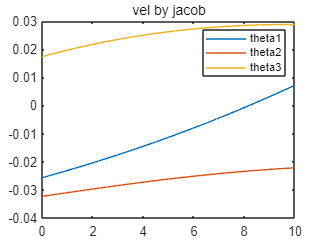

dt = 0.02;
t_sq = 0:dt:10;
N = length(t_sq);
pose_sq = [linspace(193.46*1e-3, 210*1e-3, N);
           linspace(deg2rad(-15), deg2rad(15), N);
           linspace(deg2rad(-15), deg2rad(15), N)];
endSE3_sq = zeros(4,4,N);
P_SE3_sq = zeros(4,4,N);
thetas_sq = zeros(3,N);
thetas_sim_sq = zeros(3,N);
vel_jacob_sq = zeros(3,N-1);

%compute twists & actuation jacob
endTwist_sq = zeros(6,N-1);
P_Twist_sq = zeros(6,N-1);
J_a = zeros(3,6,N);

for i=1:N
    [endSE3_sq(:,:,i), P_SE3_sq(:,:,i)] = RRS_2RRU.setEndEffectorSE3(pose_sq(1, i), pose_sq(2, i), pose_sq(3, i));
    thetas_sq(:, i) = RRS_2RRU.invKineUpdate(endSE3_sq(:,:,i));
    thetas_sim_sq(:, i) = offsetThetaSim(thetas_sq(:, i));
    J_a(:,:,i) = RRS_2RRU.getActuationJacob();

    if i>1
       % get body twist
       endTwist_sq(:, i-1) = logMapSE3(endSE3_sq(:,:,i-1) \ endSE3_sq(:,:,i)) / dt; 
       P_Twist_sq(:, i-1) = logMapSE3(P_SE3_sq(:,:,i-1) \ P_SE3_sq(:,:,i)) / dt;
       % trans to world frame
       R_end = endSE3_sq(1:3,1:3,i-1);
       R_P = P_SE3_sq(1:3,1:3,i-1);
       endTwist_sq(:, i-1) = blkdiag(R_end,R_end) * endTwist_sq(:, i-1); %dX_tool
       P_Twist_sq(:, i-1) = blkdiag(R_P,R_P) * P_Twist_sq(:, i-1); %dX_p
       %get velocity by actuation jacob
       vel_jacob_sq(:, i-1) = J_a(:,:,i-1) * P_Twist_sq(:, i-1);
    end
end

vel_diff = diff(thetas_sq, 1, 2) / dt;

figure()
plot(t_sq(1:end-1), vel_jacob_sq);
title("vel by jacob");  legend("theta1", "theta2", "theta3");

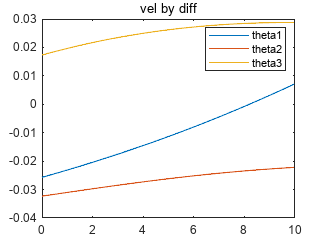


figure()
plot(t_sq(1:end-1), vel_diff);
title("vel by diff");   legend("theta1", "theta2", "theta3");

3.测试逆向静力学模块

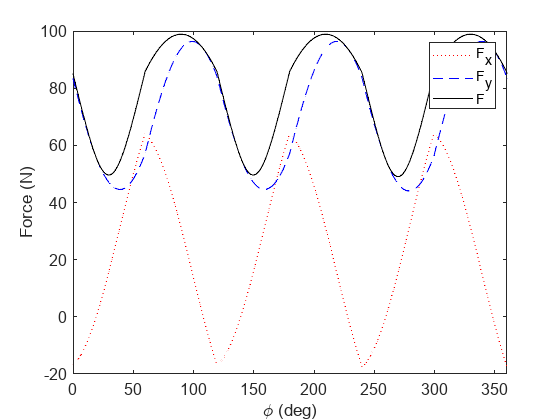

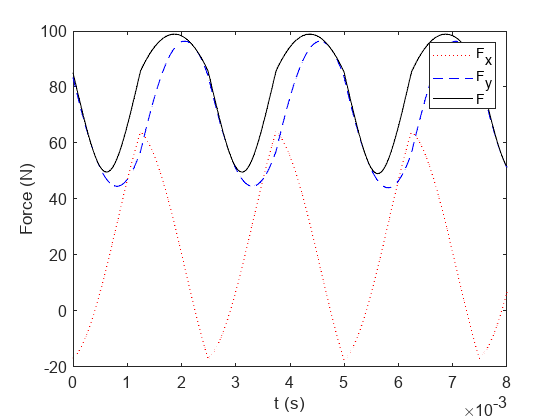

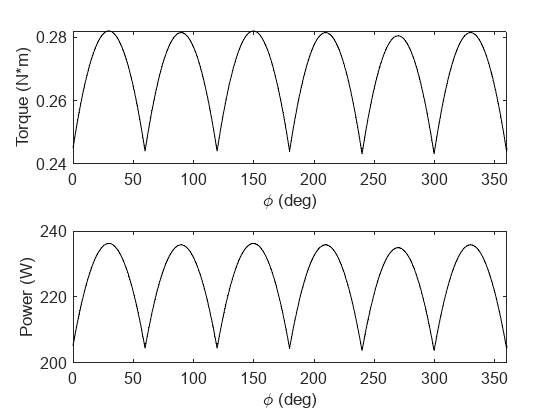

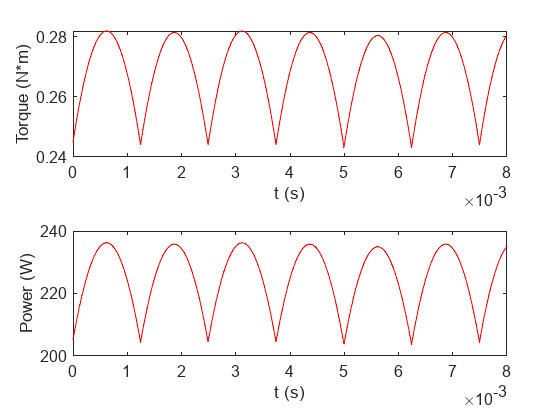

% 参数
Ks=791;
beta=71.6;
a_p = 1;
feedRate = 50; %mm/s
d = 6;
Nt = 3;
omega = 8000;

% 理论交变切削力
[Force_x, Force_y, Force, Torque, Power, t, phi] = getSlotMillingForce(Ks, beta, a_p, ...
                                                    feedRate, d, Nt, omega, 1000);

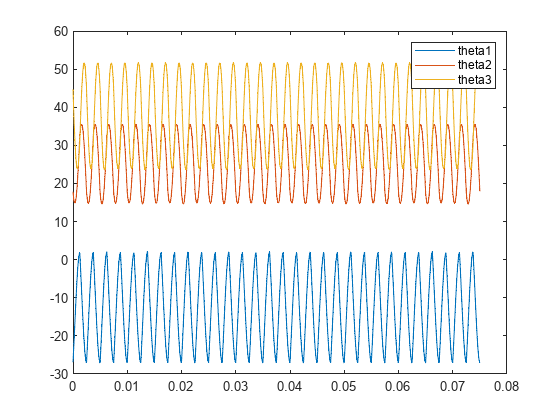

F_max = max(Force);

% 经验公式切削力
F_c = roughMillingForce(feedRate, Nt, d, a_p, d, omega);

% 修正交变力
k_m = F_c/F_max;
Force_x_m = k_m*Force_x;
Force_y_m = k_m*Force_y;
Force_m = k_m*Force;
Torque_m = k_m*Torque;
Power_m = k_m*Power;

% save related_params_verification\milling_force.mat Power_m Torque_m...
%     Force_y_m Force_x_m Force_m t phi -mat;
% 
% save related_params_verification\power.mat t Power_m -mat
% save related_params_verification\torque.mat t Torque_m -mat
% save related_params_verification\force_y.mat t Force_y_m -mat
% save related_params_verification\force_x.mat t Force_x_m -mat
% save related_params_verification\force.mat t Force_m -mat

% 静力学
% P_pose = [240*1e-3, deg2rad(15), deg2rad(15)]; %[z_p, alpha, beta]
P_pose = [193.46*1e-3, 0, 0]; %[z_p, alpha, beta]
[Tf_BTC, Tf_P] = RRS_2RRU.setEndEffectorSE3(P_pose(1), P_pose(2), P_pose(3));
thetas = RRS_2RRU.invKineUpdate(Tf_BTC); %invkine

torque_actuate = zeros(3, length(t));
for i=1:length(t)
    torque_actuate(1:3, i) = RRS_2RRU.getStaticForce_tool([0;0;Torque_m(i)], [Force_x_m(i);Force_y_m(i);0]);
end
figure()
plot(t, torque_actuate);
legend("theta1", "theta2", "theta3");

3.测试指标